# EE525 - Lab Project 2

Author: Grant Gallagher

Due: 10/15/2021

% Initialization
clc
clear

% Filter data
raw_data = readtable('raw_temp_data.csv');
temps_la = get_weather(raw_data, 'LOS ANGELES DOWNTOWN USC, CA US');
temps_sf = get_weather(raw_data, 'SAN FRANCISCO DOWNTOWN, CA US');
temps_dc = get_weather(raw_data, 'NATIONAL ARBORETUM DC, MD US');

## 2. Weather Data Analysis

In this problem, we want to determine if the annual temperatures are increasing over the last 100 years using linear regression.

Collect the temperature data (consider both average temperature and max temperature) for the following three locations: Los Angeles, San Francisco, and Washington DC from the National Climate Data Center website ([https://www.ncdc.noaa.gov/cdo-web/](https://www.ncdc.noaa.gov/cdo-web/), choose a station from each city that has a long period of record).

- Assume $X\left\lbrack n\right\rbrack$ is the annual temperature in Los Angeles for year $n$. To confirm or dispute this supposition, assume that $\mu_X \left\lbrack n\right\rbrack =a\;n+b$ and determine if $a>n$, as would be the case if the means were increasing. Estimate $a$ by using least squares, that is to choose $a$ and $b$ that minimizes the least squares error $J\left(a,b\right)=\sum_{n=1}^N \left\lbrack {\left\lbrack x_n -\left(an+b\right)\right\rbrack }^2 \right\rbrack$.

- Plot the straight line derived in Step 1 to the sample data.

- Plot the least squares error sequence $e\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -\left(\hat{\;a} n+\hat{\;b} \right)$, and find the error varience.

- What's the predicted annual temperature in 2021 for Los Angeles bases on the past data and linear regression model?

- Repeat the above steps for the temperature data in the other two locations.

- What conclusions can one draw based on the above analyses.

### 2.1 Average Temperatures

#### Los Angeles

% Average Temperature Plots
fig1 = figure(1);
fig1.Position = [0 0 600 300];
[a, b] = least_squares(temps_la, 'Tavg')

a = 0.0372

b = -8.0244

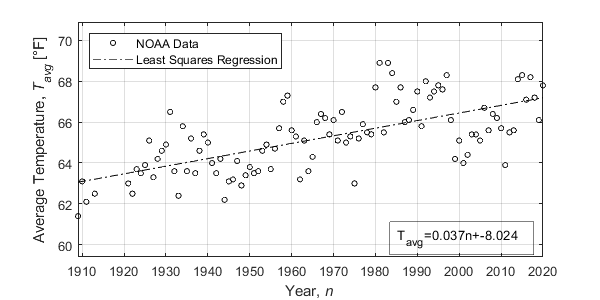

plot_regression(temps_la, a, b, 'Tavg')
saveas(fig1, "LA avg regression.jpg");

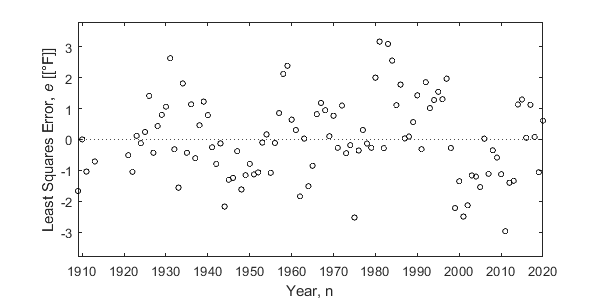


% Average Temperature Error Sequence
fig2 = figure(2);
fig2.Position = [0 0 600 300];
plot_errors(temps_la, a, b, 'Tavg')
saveas(fig2, "LA avg error.jpg");

varience(temps_la(:,2))

ans = 2.9332

#### San Francisco

% Average Temperature Plots
fig3 = figure(3);
fig3.Position = [0 0 600 300];
[a, b] = least_squares(temps_sf, 'Tavg')

a = 0.0150

b = 27.8750

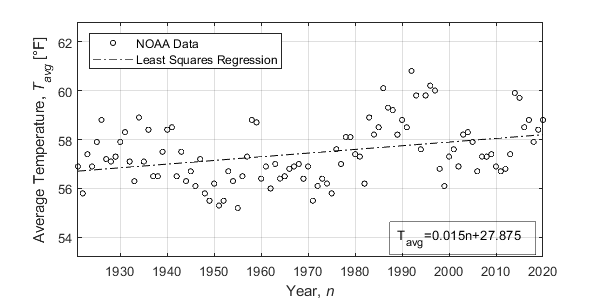

plot_regression(temps_sf, a, b, 'Tavg')
saveas(fig3, "SF avg regression.jpg");

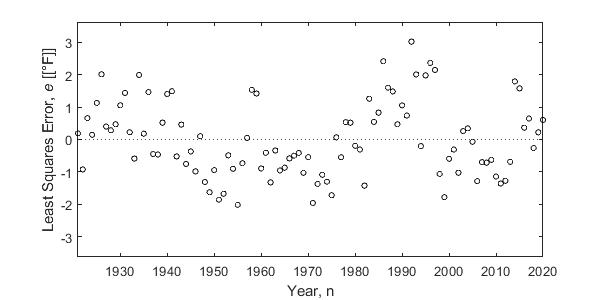


% Average Temperature Error Sequence
fig4 = figure(4);
fig4.Position = [0 0 600 300];
plot_errors(temps_sf, a, b, 'Tavg')
saveas(fig4, "SF avg error.jpg");

varience(temps_sf(:,2))

ans = 1.5056

#### Washington DC

% Average Temperature Plots
fig5 = figure(5);
fig5.Position = [0 0 600 300];
[a, b] = least_squares(temps_dc, 'Tavg')

a = 0.0263

b = 4.8749

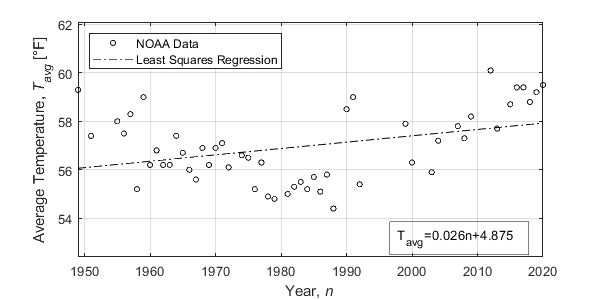

plot_regression(temps_dc, a, b, 'Tavg')
saveas(fig5, "DC avg regression.jpg");

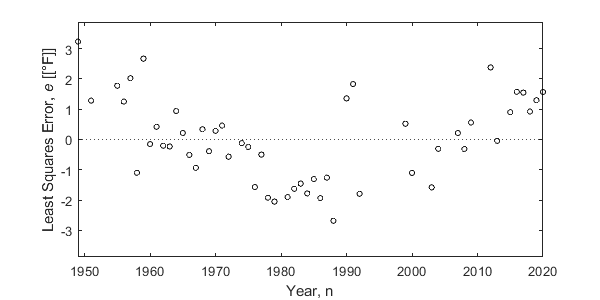


% Average Temperature Error Sequence
fig5 = figure(6);
fig5.Position = [0 0 600 300];
plot_errors(temps_dc, a, b, 'Tavg')
saveas(fig5, "DC avg error.jpg");

### 2.2 Maximum Temperatures

#### Los Angeles

% Maximum Temperature Plots
fig7 = figure(7);
fig7.Position = [0 0 600 300];
[a, b] = least_squares(temps_la, 'Tmax')

a = 0.0385

b = -1.3932

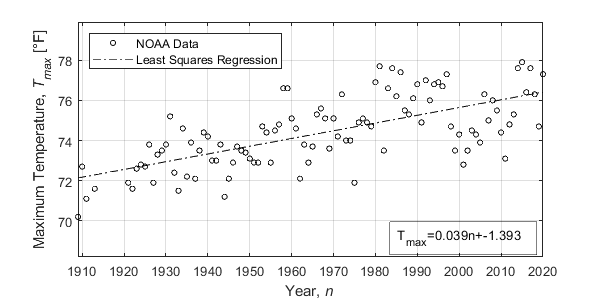

plot_regression(temps_la, a, b, 'Tmax')
saveas(fig7, "LA max regression.jpg");

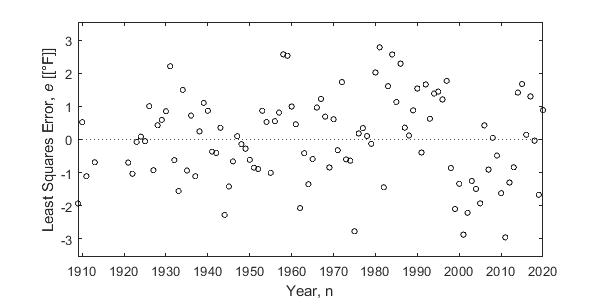


% Maximum Temperature Error Sequence
fig8 = figure(8);
fig8.Position = [0 0 600 300];
plot_errors(temps_la, a, b, 'Tmax')
saveas(fig8, "LA max error.jpg");

varience(temps_la(:,2))

ans = 2.9332

#### San Francisco

% Maximum Temperature Plots
fig9 = figure(9);
fig9.Position = [0 0 600 300];
[a, b] = least_squares(temps_sf, 'Tmax')

a = 0.0207

b = 22.9098

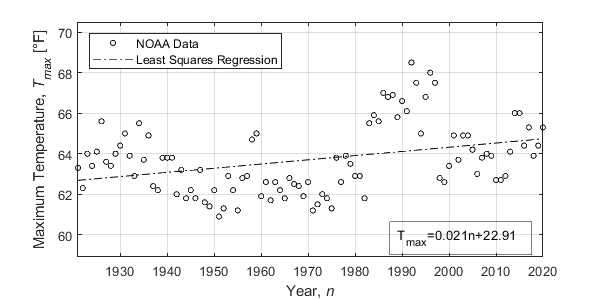

plot_regression(temps_sf, a, b, 'Tmax')
saveas(fig9, "SF max regression.jpg");

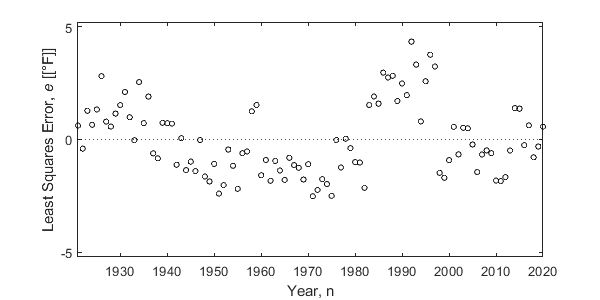


% Maximum Temperature Error Sequence
fig10 = figure(10);
fig10.Position = [0 0 600 300];
plot_errors(temps_sf, a, b, 'Tmax')
saveas(fig10, "SF max error.jpg");

varience(temps_sf(:,2))

ans = 1.5056

#### Washington DC

% Maximum Temperature Plots
fig11 = figure(11);
fig11.Position = [0 0 600 300];
[a, b] = least_squares(temps_dc, 'Tmax')

a = 0.0071

b = 53.3871

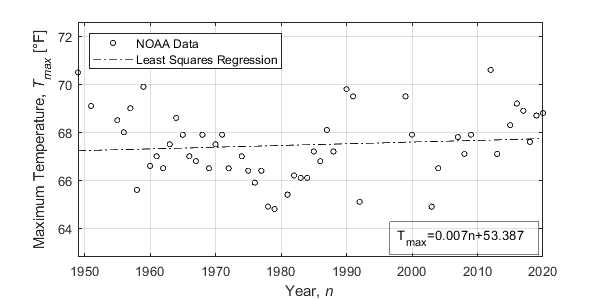

plot_regression(temps_dc, a, b, 'Tmax')
saveas(fig11, "DC max regression.jpg");

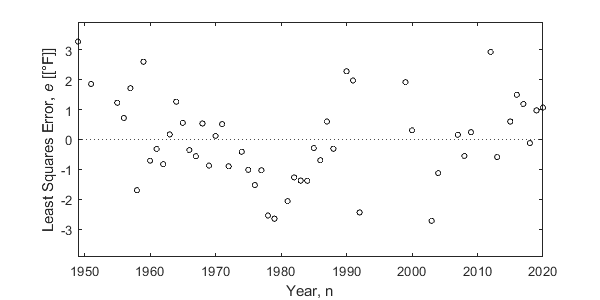


% Maximum Temperature Error Sequence
fig12 = figure(12);
fig12.Position = [0 0 600 300];
plot_errors(temps_dc, a, b, 'Tmax')
saveas(fig12, "DC max error.jpg");

## 3. Appendices

### 3.1 get_weather()

function temperature_history = get_weather(raw_data, location)
    % Extract temperatures and years
    years = raw_data.DATE(string(raw_data.NAME) == location);
    average_temperatures = raw_data.TAVG(string(raw_data.NAME) == location);
    max_temperatures = raw_data.TMAX(string(raw_data.NAME) == location);
    % Return valid data points
    temperature_history = rmmissing([years average_temperatures max_temperatures]);
end

### 3.2 least_squares()

function [a, b] = least_squares(data, temperature)
    if temperature == 'Tavg'
        idx = 2;
    elseif temperature == 'Tmax'
        idx = 3;
    else
        disp('Error.');
        return
    end
    % Calculate the average values for n and x[n]
    n_avg = average(data(:,1));
    x_avg = average(data(:,idx));
    
    % Calculate the "Sum of Squares" and "Sum of Products"
    SP = sum((data(:,1)-n_avg).*(data(:,idx)-x_avg));
    SS = sum((data(:,1)-n_avg).^2);
    
    % Calculate the values for a and b
    a = SP/SS;
    b = x_avg - a*n_avg;
end

### 3.3 plot_regression()

function plot_regression(data, a, b, temperature)
    syms x
    if temperature == 'Tavg'
        idx = 2;
    elseif temperature == 'Tmax'
        idx = 3;
    else
        disp('Error.');
        return
    end
    
    hold on
    plot(data(:,1), data(:,idx),'o','Color',[0 0 0],'MarkerSize',4);
    fplot(a*x+b,'-.','Color',[0 0 0]);
    hold off
    grid on
    box on
    
    xlim([min(data(:,1)) max(data(:,1))]);
    ylim([min(data(:,idx))-2 max(data(:,idx))+2]);

    legend('NOAA Data','Least Squares Regression', 'Location','NorthWest');
    xlabel('Year, {\itn}')
    if temperature == 'Tavg'
        ylabel('Average Temperature, {\itT_{avg}} [°F]');
        str = 'T_{avg}='+string(round(a,3))+'n+'+string(round(b,3));
    elseif temperature == 'Tmax'
        ylabel('Maximum Temperature, {\itT_{max}} [°F]');
        str = 'T_{max}='+string(round(a,3))+'n+'+string(round(b,3));
    end
    dim = [0.65 .2 .06 .06];
    annotation('textbox',dim,'String',str,'FitBoxToText','on');
end

### 3.4 varience()

function sigma_2 = varience(S)
    sigma_2 = sum((S-average(S)).^2)/(length(S)-1);
end

### 3.5 average()

function mu = average(S)
    mu = sum(S)/length(S);
end

### 3.6 plot_errors()

function plot_errors(data, a, b, temperature)
    if temperature == 'Tavg'
            idx = 2;
        elseif temperature == 'Tmax'
            idx = 3;
        else
            disp('Error.');
            return
    end
    
    e = length(data);
    for n = 1:length(data)
        e(n) = data(n,idx)-(a*data(n,1)+b);
    end
    
    hold on
    plot(data(:,1),e,'o','Color',[0 0 0],'MarkerSize',4)
    yline(0,':','Color',[0 0 0]);
    hold off
    box on
    
    xlim([min(data(:,1)) max(data(:,1))]);
    ylim([-max(abs(e))*1.2 max(abs(e))*1.2])
    
    xlabel('Year, n')
    ylabel('Least Squares Error, {\ite} [[°F]]')
end